clc; 
clear;
syms x h a

%f = 4*x^2 - 2*x -4; % Source term
f = -1

f = -1

e = 10;
% No of Nodal points
nodes =e+1;

% numerical values for a, c, and h
a_num = 1;
% domain of X
x0 = 0;
xL = 1;

P = 3; % hermitie cubic shape Functions

phi_e = H_Cubic_beam_shapefunction_x(x0);

% Element length
h_num = (xL - x0) / e;

DOF_e =4;
%Degree of Freedom per element


% Local stiffness matrix
KNM_local = zeros(DOF_e, DOF_e, 'sym');
CNM_local = zeros(DOF_e, DOF_e, 'sym');


for N = 1:DOF_e
    for M = 1:DOF_e
        % Integrate to get the local stiffness matrix
        KNM_local(N, M) = int(a * diff(phi_e(N), x,2) * diff(phi_e(M), x,2),0,h_num);
        CNM_local(N, M) = int( phi_e(N) * phi_e(M), x, 0, h);
    end
end

% % Display the local stiffness matrix
% disp('Local Stiffness Matrix some element e:');
% disp(KNM_local);


% Substitute values into the local  matrices
KNM_local_sub = double(subs(KNM_local, {a, h}, {a_num,h_num}));
CNM_local_sub = subs(CNM_local, h, h_num);

% % Display the substituted local stiffness matrix
% disp('Substituted values of a c and h in Local Stiffness Matrix:');
% disp(KNM_local_sub);
% disp('Substituted value h in Local C_NM Matrix:');
% disp(CNM_local_sub);




% Define degrees of freedom per node
DOF_e = 2;

% Total degrees of freedom
total_DOF = nodes * DOF_e;

% Initialize global stiffness matrix
K_global = zeros(total_DOF);
C_global = zeros(total_DOF);


% Assemble the global stiffness matrix
for i = 1:e
    % Global DOF indices for the current element
    start_index = (i-1) * DOF_e + 1;
    end_index = start_index + 2 * DOF_e - 1;

    % Assign local to global
    global_indices = start_index:end_index;
    K_global(global_indices, global_indices) = K_global(global_indices, global_indices) + KNM_local_sub;
    C_global(global_indices, global_indices) = C_global(global_indices, global_indices) + CNM_local_sub;
end

% % Display the global stiffness matrix
% disp('Global Stiffness Matrix:');
% disp(K_global);
% 
% disp('Global C Matrix:')
% disp(C_global);
% Source vector Initialization 



% Source vector Initialization 
f_x = sym(zeros(nodes, 1));
% Calculate f(x) for each x value symbolically and store in the vector

X = x0:h_num:xL;

for i = 1:nodes
    f_x(i) = subs(f, x, X(i));
end
f_x = [f_x,f_x];

f_x = matrixToColumnVector(f_x);



Fv = double(C_global*f_x); %Fvector


% Get the handle of the command window
commandwindow;

prompt_x0 = 'Enter the type of boundary condition at x0 (1. Fixed, 2. Roller, 3. Free end): ';
type_x0 = input(prompt_x0);

switch type_x0
    case 1
        y0 = 0;  % Displacement at x0 is zero (Fixed end)
        theta0 = 0;  % Rotation at x0 is zero
    case 2
        y0  = 0;
        M0 = 0;  
    case 3
        % No boundary conditions to apply (Free end)
        % You can leave this section empty or add a comment like this.
    otherwise
        error('Invalid boundary condition type at x0');  % Handle invalid inputs
end



% Prompt the user to input boundary conditions at xL
prompt_xL = 'Enter the type of boundary condition at xL (1. Fixed, 2. Roller, 3. Free end): ';
type_xL = input(prompt_xL);

switch type_xL
    case 1
        yL = 0;  % Displacement at x0 is zero (Fixed end)
        thetaL = 0;  % Rotation at x0 is zero
    case 2
        yL = 0;
        ML = 0;  
    case 3
        % No boundary conditions to apply (Free end)
        % You can leave this section empty or add a comment like this.
    otherwise
        error('Invalid boundary condition type at xL');
end


% Prompt the user to input information about loads on the beam
prompt_load = 'Is there a load or moment present on the beam? (1. Point Load, 2. Moment, 3. Both, 4. None): ';
loadResponse = input(prompt_load);

switch loadResponse
    case 1  % Point Load
        P_val = input('Enter the value of the point load: ');
        P_loc = input('Enter the location of the point load: ');
        [P_index, is_on_node] = check_location(P_loc, 'Point Load', x0, xL, e);
        if is_on_node
            disp(['Point Load is at node index: ', num2str(P_index)]);
        end

    case 2  % Moment
        M_val = input('Enter the value of the moment: ');
        M_loc = input('Enter the location of the moment: ');
        [M_index, is_on_node] = check_location(M_loc, 'Moment', x0, xL, e);
        if is_on_node
            disp(['Moment is at node index: ', num2str(M_index)]);
        end

    case 3  % Both Point Load and Moment
        P_val1 = input('Enter the value of the point load: ');
        P_loc1 = input('Enter the location of the point load: ');
        M_val1 = input('Enter the value of the moment: ');
        M_loc1 = input('Enter the location of the moment: ');
        [indices, are_on_nodes] = check_both_locations(P_loc1, M_loc1, x0, xL, e);

        P_index1 = indices(1);
        M_index1 = indices(2);

        if are_on_nodes(1)
            disp(['Point Load is at node index: ', num2str(P_index1)]);
        end
        if are_on_nodes(2)
            disp(['Moment is at node index: ', num2str(M_index1)]);
        end

    case 4  % None
        disp('No load or moment present, continuing with the rest of the code.');

    otherwise
        error('Invalid response. Please enter a valid option (1-4).');
end

No load or moment present, continuing with the rest of the code.




Gv = zeros(total_DOF, 1);

if exist('P_index', 'var') && exist('P_loc', 'var') && exist('P_val', 'var')
    Gv(2*P_index) = P_val
end

if exist('M_index', 'var') && exist('M_loc', 'var') && exist('M_val', 'var')
    Gv( (2*M_index)+1 ) = M_val
end

if exist('P_index1', 'var') && exist('P_loc1', 'var') && exist('P_val1', 'var')
    Gv(2*P_index1) = P_val1
end

if exist('M_index1', 'var') && exist('M_loc1', 'var') && exist('M_val1', 'var')
    Gv( (2*M_index1)+1 ) = M_val1
end

RHS = Fv + Gv;

if exist('y0', 'var') && exist('theta0', 'var')

    K_global(1,:)= [1,zeros(1, total_DOF-1)];
    K_global(2,:)= [0,1,zeros(1, total_DOF-2)];
    
    RHS(1) = y0;
    RHS(2) = theta0;
end

if exist('y0', 'var') && exist('M0', 'var')

   K_global(1,:)= [1,zeros(1, total_DOF-1)];
   RHS(1) =M0;
end

if exist('yL', 'var') && exist('thetaL', 'var')
    K_global(end-1,:) = [zeros(1, total_DOF)];
    K_global(end-1, end-1) = 1;

    K_global(end,:)= [zeros(1, total_DOF-1),1];
    RHS(end-1) = yL;
    RHS(end) = thetaL;

end

if exist('yL', 'var') && exist('ML', 'var')

    K_global(end-1,:) = [zeros(1, total_DOF)];
    K_global(end-1, end-1) = 1;

    RHS(end-1) =ML;
end


UVUV = K_global\RHS;

UV = columnVectorToMatrix(UVUV);

deflection = UV(:,1);
Slope = UV(:,2);

% myTable = table(X', deflection, Slope,'VariableNames', {'Nodal point', 'Deflection','slope'});
% disp(myTable);
% disp("-------------------------------------------------------------")

Nnodes_e = 2; % for beam

[element_numbers,interpolating_functions,ranges,Bmoment1] = diff_Function(Slope,X',Nnodes_e,e);

% Create and display the table
Table1 = table(element_numbers, interpolating_functions, ranges, ...
          'VariableNames', {'Element Number', 'Interpolating Function', 'Range'});
%disp(Table1);
BMoment = -a_num*Bmoment1;


[element_numbers1,interpolating_functions1,ranges1,SF1] = diff_Function(Bmoment1',X',Nnodes_e,e);

% Create and display the table
Table2 = table(element_numbers1, interpolating_functions1, ranges1, ...
          'VariableNames', {'Element Number', 'Interpolating Function', 'Range'});
%disp(Table1);
SF = -a_num*SF1;

myTable = table(X', deflection, Slope,BMoment',SF','VariableNames', {'Nodal point', 'Deflection','Slope','BM','SF'});
disp(myTable);

    Nodal point    Deflection       Slope           BM            SF     
    ___________    __________    ___________    __________    ___________

          0        5.2786e-16    -1.0331e-15          0.06           -0.4
        0.1        -0.0003375         -0.006          0.02           -0.3
        0.2        -0.0010667         -0.008    -0.0099999           -0.2
        0.3        -0.0018375     -0.0070001         -0.03           -0.1
        0.4           -0.0024     -0.0040001         -0.04    -4.7619e-07
        0.5        -0.0026042    -5.9524e-08         -0.04            0.1
        0.6           -0.0024      0.0039999         -0.03            0.2
        0.7        -0.0018375      0.0069999         -0.01            0.3
        0.8        -0.0010667          0.008          0.02            0.4
        0.9    

disp("-------------------------------------------------------------")

-------------------------------------------------------------


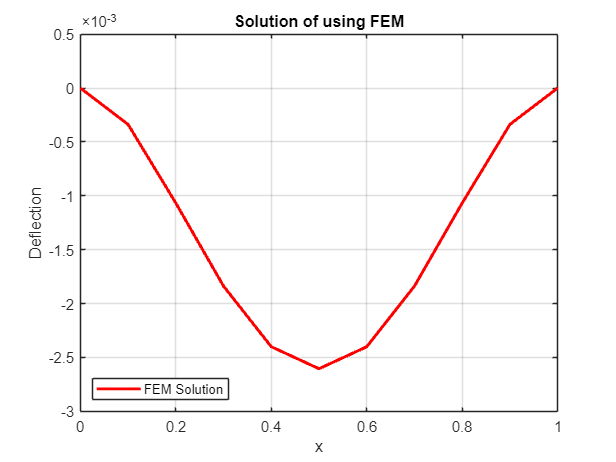


figure(1);
plot(X, deflection, "r", "LineWidth", 2, "DisplayName", "FEM Solution"); 
xlabel("x");
ylabel("Deflection");
title("Solution of using FEM");
legend('Location', 'southwest');
grid on;

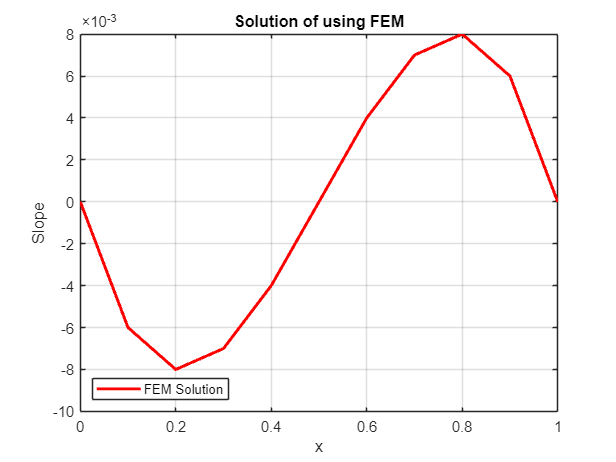


figure(2);
plot(X, Slope, "r", "LineWidth", 2, "DisplayName", "FEM Solution"); 
xlabel("x");
ylabel("Slope");
title("Solution of using FEM");
legend('Location', 'southwest');
grid on;

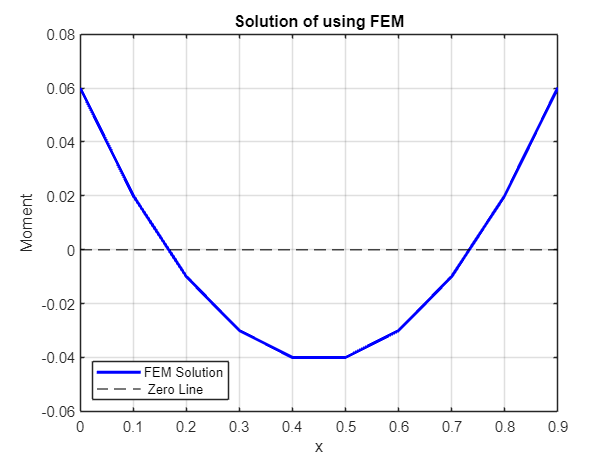



figure(3);
plot(X, BMoment, "b", "LineWidth", 2, "DisplayName", "FEM Solution"); 
xlabel("x");
ylabel("Moment");
title("Solution of using FEM");
legend('Location', 'southwest');
hold on; % Keeps the current plot
% Add a horizontal line at y = 0
yline(0, 'k--',"LineWidth",1, "DisplayName", " Zero Line");
grid on;
% Due to diff function last limit i don't have proper value
Last_value = xL-h_num;
xlim([x0 Last_value]);
hold off;

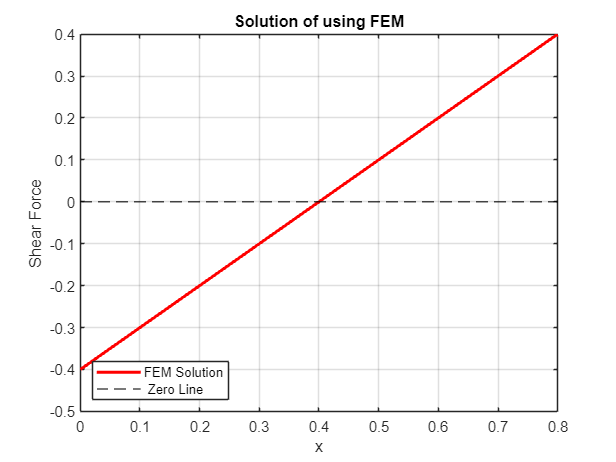


figure(4);
plot(X, SF, "r", "LineWidth", 2, "DisplayName", "FEM Solution"); 
xlabel("x");
ylabel("Shear Force");
title("Solution of using FEM");
legend('Location', 'southwest');
hold on; % Keeps the current plot
% Add a horizontal line at y = 0
yline(0, 'k--',"LineWidth",1, "DisplayName", " Zero Line"); % Adds a red horizontal line at y = 0
grid on;
% Due to two times diff function last limit i don't have proper value
Last_value1 = Last_value-h_num;
xlim([x0 Last_value1]);
hold off;

function [index, is_on_node] = check_location(location, type, x0, xL, e)
    x_vector = GlobalLocationBeam(x0, xL, e);
    is_on_node = any(abs(x_vector - location) < eps); % Check if on node
    if is_on_node
        index = find(abs(x_vector - location) < eps); % Find index of the node
        disp([type, ' location is on node at index ', num2str(index), '.']);
    else
        index = [];
        disp([type, ' location is not on a node.']);
    end
end

function [indices, are_on_nodes] = check_both_locations(P_loc, M_loc, x0, xL, e)
    x_vector = GlobalLocationBeam(x0, xL, e);
    P_on_node = any(abs(x_vector - P_loc) < eps);
    M_on_node = any(abs(x_vector - M_loc) < eps);
    indices = zeros(1,2);
    are_on_nodes = [P_on_node, M_on_node];

    if P_on_node
        indices(1) = find(abs(x_vector - P_loc) < eps);
    end
    if M_on_node
        indices(2) = find(abs(x_vector - M_loc) < eps);
    end

    if all(are_on_nodes)
        disp('Both Point Load and Moment locations are on nodes.');
    else
        disp('One or neither of the Point Load and Moment locations are on nodes.');
    end
end

function x_vector = GlobalLocationBeam(x0, xL, e)
    h = (xL - x0) / e;
    x_vector = x0:h:xL; % Generates a vector of node locations
end

function phi_e = H_Cubic_beam_shapefunction_x(x0)
    %Hermite cubic shape functions
    % Define symbolic variables
    syms x x1 h real;

    % in this formula x1 is starting point of the element

    % Define the Hermite cubic shape functions as provided
    N1 = 1 - (3*((x - x1)/h)^2) + (2*((x - x1)/h)^3);


    % for JN reddy N2 here assume inverted slope, So negative must be added for N2 and N4,
    % I'm following Dixit notation, ( Notes Only N2 and N4 are Different )

    N2 = (x - x1) * ((1-((x - x1)/h))^2);
    N3 = (3*((x - x1)/h)^2) - (2*((x - x1)/h)^3);
    N4 = (x - x1)*(((-((x - x1)/h)) + (((x - x1)/h)^2)));
    
    phi_e = sym(zeros(4,1));
    
    phi_e(1) = N1;
    phi_e(2) = N2;
    phi_e(3) = N3;
    phi_e(4) = N4;
    phi_e = subs(phi_e,x1,x0);

end
function B = matrixToColumnVector(A)
    % matrixToColumnVector converts a n x 2 matrix into a 2n x 1 column vector.

    % Check if the input matrix A has exactly 2 columns
    if size(A, 2) ~= 2
        error('Input matrix must have exactly 2 columns');
    end

    % Reshape the matrix A to a column vector
    B = reshape(A', [], 1);

    % Optionally, display the output vector
    % disp(B);  % Uncomment this line if you want to display the vector
end
function A = columnVectorToMatrix(B)
    % columnVectorToMatrix converts a 2n x 1 column vector into a n x 2 matrix.

    % Check if the length of vector B is even
    if mod(length(B), 2) ~= 0
        error('Length of input vector must be even');
    end

    % Calculate the number of rows for the matrix A
    numRows = length(B) / 2;

    % Reshape the vector B to a matrix A of size n x 2
    A = reshape(B, 2, numRows)';

    % Optionally, display the output matrix
    % disp(A);  % Uncomment this line if you want to display the matrix
end


function [element_numbers,interpolating_functions,ranges,Fun_prime_values] = diff_Function(SomeFunVal,X_nodes,Nnodes_e,e)

% Nnodes_e for element
S = numel(X_nodes);
syms x
SomeFunVal =  SomeFunVal';
X_nodes = X_nodes';

% Initialize storage for table contents
element_numbers = (1:e)';
interpolating_functions = cell(e, 1);
ranges = cell(e, 1);


i =1;
% Initialize storage for u' values
Fun_prime_values = zeros(S,1)';
index =1;

for element = 1:Nnodes_e-1:S-1

    start_index = element;
    end_index = element + Nnodes_e-1;
    x_node_loc = X_nodes(start_index:end_index); % Extract node locations for the current element
    u_node_value = SomeFunVal(start_index:end_index); % Extract node values for the current element
    
    % Perform Lagrange interpolation (assuming you have a function that does this)
    [~, Lagrange_polynomial] = lagrange_interpolation(Nnodes_e, x_node_loc, u_node_value);
    
    % Derive u' from the Lagrange polynomial
    Lagrange_derivative = diff(Lagrange_polynomial, x);
    
    % Evaluate u' at all nodal points within the element's range except for the last point
    for xi = x_node_loc(1:end-1)
        u_prime_value = double(subs(Lagrange_derivative, x, xi));
        Fun_prime_values(index) = u_prime_value;
        index = index+1;
    end

    if e == i
        Fun_prime_values(end) = double(subs(Lagrange_derivative, x, X_nodes(end)));
    end


    % Store the results
    interpolating_functions{i} = char(Lagrange_polynomial);
    ranges{i} = sprintf('[%g, %g]', x_node_loc(1), x_node_loc(end));

    i = i+1;
end

end

